# General variables

## Simulation variables

SNRdB = 10;                % SNR in dB (Usused ATM)

totalNoSlots = 1000;          % Number slots containing information simulated

perfectEstimation = false; % Perfect synchronization and channel estimation (Unused ATM)
rng("default");            % Set default random number generator for repeatability

fileID = fopen('Bits.bin','r'); %send bit file
fileID2 = fopen('RecBits.bin','w'); %recieve bit file


## Carrier config

carrier = nrCarrierConfig

carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


carrier.NCellID = 1;
carrier.SubcarrierSpacing = 15;
carrier.CyclicPrefix = 'normal';
carrier.NSizeGrid;
carrier.NSlot;
carrier.NFrame;
carrier.IntraCellGuardBands;

%Read-Only variables
%SymbolsPerSlot: Number of OFDM symbols per slot bases on CyclePrefix
%SlotsPerSubFrame: Number of Slots per 1ms frame, based of the subcarrierspacing
%SlotsPerFrame: Number of Slots per 10ms frame, based of the subcarrierspacing

## Physical Downlink Shared Channel

pdsch = nrPDSCHConfig;
pdsch.NSizeBWP;
pdsch.NStartBWP;
pdsch.ReservedPRB;
pdsch.ReservedRE;
pdsch.Modulation = "16QAM";
pdsch.NumLayers = 1;
pdsch.MappingType;
pdsch.SymbolAllocation;
pdsch.PRBSet = 0:carrier.NSizeGrid-1;     % Full band allocation
pdsch.PRBSetType;
pdsch.VRBToPRBInterleaving;
pdsch.VRBBundleSize;
pdsch.NID;
pdsch.RNTI;

## PDSCH-DeModulation Refrence Signal

pdsch.DMRS.DMRSConfigurationType = 1;
pdsch.DMRS.DMRSReferencePoint;
pdsch.DMRS.DMRSTypeAPosition; 
pdsch.DMRS.DMRSAdditionalPosition;
pdsch.DMRS.DMRSLength = 2;
pdsch.DMRS.CustomSymbolSet; 
pdsch.DMRS.DMRSPortSet;
pdsch.DMRS.NIDNSCID; 
pdsch.DMRS.NSCID; 
pdsch.DMRS.NumCDMGroupsWithoutData;
pdsch.DMRS.DMRSDownlinkR16;
pdsch.DMRS.CDMGroups;
pdsch.DMRS.DeltaShifts;
pdsch.DMRS.FrequencyWeights;
pdsch.DMRS.TimeWeights;
pdsch.DMRS.DMRSSubcarrierLocations;
pdsch.DMRS.CDMLengths;
pdsch.DMRS

ans =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 0
                 DMRSLength: 2
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2
            DMRSDownlinkR16: 0

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]


## DL-SCH Configuration

NHARQProcesses = 1;     % Number of parallel HARQ processes
rvSeq = 0;              % 0 = disabled HARQ retransmission incase of an error

% Coding rate
if pdsch.NumCodewords == 1 
    codeRate = 490/1024; %For up to 4 layers 
else
    codeRate = [490 490]./1024; %For above 4 layers
end


% Create DL-SCH encoder object
encodeDLSCH = nrDLSCH;
encodeDLSCH.MultipleHARQProcesses = true;
encodeDLSCH.TargetCodeRate = codeRate;

% Create DLSCH decoder object
decodeDLSCH = nrDLSCHDecoder;
decodeDLSCH.MultipleHARQProcesses = true;
decodeDLSCH.TargetCodeRate = codeRate;
decodeDLSCH.LDPCDecodingAlgorithm = "Normalized min-sum";
decodeDLSCH.MaximumLDPCIterationCount = 6;

## HARQ Management

harqEntity = HARQEntity(0:NHARQProcesses-1,rvSeq,pdsch.NumCodewords);

## Channel Configuration

nTxAnts = 1;
nRxAnts = 1;

% Check that the number of layers is valid for the number of antennas
if pdsch.NumLayers > min(nTxAnts,nRxAnts)
    error("The number of layers ("+string(pdsch.NumLayers)+") must be smaller than min(nTxAnts,nRxAnts) ("+string(min(nTxAnts,nRxAnts))+")")
end

channel = nrTDLChannel;
channel.DelayProfile = "TDL-C";
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;

ofdmInfo = nrOFDMInfo(carrier);
channel.SampleRate = ofdmInfo.SampleRate;

## Transmission and Reception

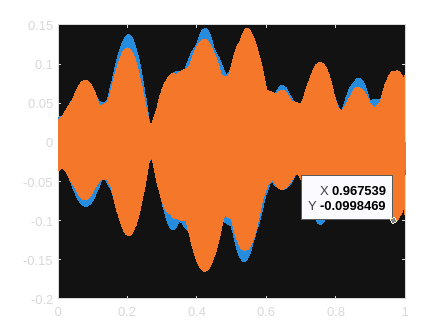

constPlot = comm.ConstellationDiagram;                                          % Constellation diagram object
constPlot.ReferenceConstellation = getConstellationRefPoints(pdsch.Modulation); % Reference constellation values
constPlot.EnableMeasurements = 1;                                               % Enable EVM measurements

% Initial timing offset
offset = 0;

longwave = 0.00001+0.00001i;

delay = 0.001+0.001i;

estChannelGrid = getInitialChannelEstimate(channel,carrier);
newPrecodingWeight = getPrecodingMatrix(pdsch.PRBSet,pdsch.NumLayers,estChannelGrid);

for nSlot = 0:totalNoSlots-1
     carrier.NSlot = nSlot;

    [txWaveform, waveformInfo, trBlk, trBlkSizes] = TransmitterEntity(carrier, pdsch, encodeDLSCH, harqEntity, nSlot, newPrecodingWeight, codeRate, fileID, nTxAnts, decodeDLSCH);


    chInfo = info(channel);
    maxChDelay = chInfo.MaximumChannelDelay;
    txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))];
    


    [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
    %noise = generateAWGN(SNRdB,nRxAnts,waveformInfo.Nfft,size(rxWaveform));
    %rxWaveform = rxWaveform + noise;
    longwave = cat(1, longwave,rxWaveform);
end


time = totalNoSlots*1e-3;
length = totalNoSlots*15371+1;

x = 0:65e-9:time;
x = rot90(x);
x=x(1:length, 1);
plot(x, real(longwave),x, imag(longwave))

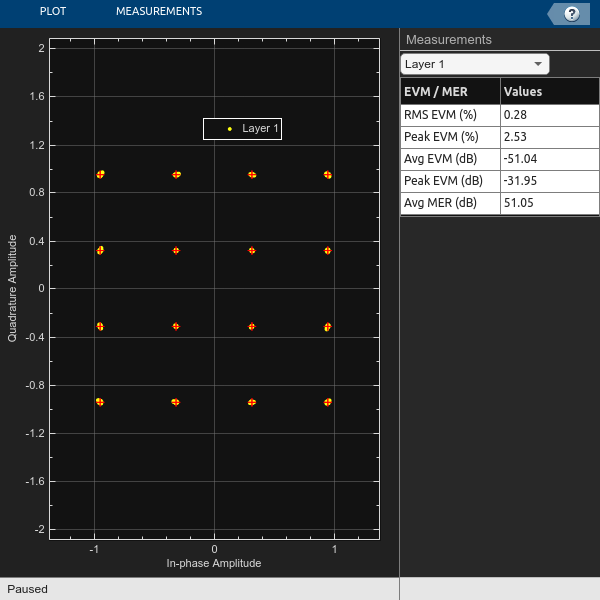

Slot 0. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   0
   1
   0
   1
   0
   1
   0
   1
   0


pass = logical
   0


Slot 1. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


pass = logical
   0


Slot 2. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 3. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 4. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 5. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 6. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 7. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 8. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 9. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 10. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 11. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 12. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 13. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 14. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 15. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 16. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 17. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 18. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 19. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 20. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 21. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 22. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 23. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 24. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 25. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 26. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 27. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 28. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 29. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 30. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 31. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 32. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 33. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 34. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 35. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 36. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 37. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 38. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 39. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 40. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 41. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 42. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 43. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 44. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 45. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 46. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 47. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 48. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 49. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 50. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 51. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 52. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 53. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 54. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 55. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 56. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 57. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 58. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 59. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 60. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 61. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 62. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 63. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 64. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 65. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 66. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 67. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 68. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 69. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 70. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 71. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 72. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 73. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 74. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 75. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 76. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 77. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 78. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 79. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 80. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 81. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 82. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 83. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 84. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 85. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 86. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 87. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 88. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 89. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 90. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 91. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 92. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 93. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 94. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 95. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 96. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 97. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 98. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 99. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 100. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 101. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 102. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 103. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 104. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 105. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 106. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 107. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 108. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 109. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 110. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 111. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 112. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 113. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 114. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 115. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 116. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 117. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 118. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 119. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 120. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 121. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 122. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 123. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 124. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 125. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 126. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 127. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 128. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 129. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 130. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 131. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 132. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 133. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 134. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 135. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 136. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 137. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 138. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 139. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 140. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 141. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 142. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 143. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 144. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 145. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 146. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 147. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 148. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 149. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 150. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 151. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 152. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 153. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 154. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 155. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 156. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 157. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 158. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 159. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 160. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 161. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 162. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 163. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 164. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 165. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 166. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 167. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 168. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 169. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 170. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 171. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 172. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 173. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 174. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 175. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 176. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 177. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 178. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 179. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 180. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 181. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 182. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 183. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 184. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 185. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 186. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 187. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 188. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 189. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 190. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 191. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 192. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 193. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 194. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 195. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 196. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 197. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 198. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 199. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 200. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 201. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 202. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 203. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 204. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 205. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 206. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 207. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 208. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 209. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 210. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 211. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 212. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 213. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 214. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 215. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 216. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 217. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 218. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 219. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 220. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 221. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 222. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 223. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 224. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 225. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 226. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 227. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 228. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 229. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 230. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 231. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 232. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 233. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 234. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 235. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 236. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 237. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 238. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 239. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 240. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 241. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 242. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 243. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 244. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 245. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 246. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 247. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 248. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 249. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 250. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 251. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 252. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 253. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 254. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 255. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 256. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 257. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 258. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 259. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 260. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 261. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 262. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 263. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 264. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 265. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 266. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 267. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 268. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 269. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 270. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 271. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 272. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 273. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 274. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 275. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 276. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 277. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 278. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 279. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 280. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 281. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 282. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 283. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 284. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 285. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 286. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 287. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 288. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 289. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 290. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 291. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 292. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 293. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 294. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 295. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 296. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 297. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 298. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 299. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 300. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 301. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 302. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 303. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 304. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 305. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 306. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 307. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 308. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 309. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 310. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 311. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 312. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 313. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 314. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 315. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 316. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 317. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 318. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 319. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 320. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 321. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 322. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 323. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 324. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 325. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 326. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 327. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 328. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 329. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 330. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 331. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 332. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 333. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 334. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 335. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 336. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 337. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 338. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 339. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 340. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 341. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 342. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 343. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 344. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 345. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 346. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 347. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 348. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 349. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 350. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 351. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 352. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 353. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 354. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 355. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 356. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 357. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 358. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 359. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 360. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 361. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 362. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 363. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 364. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 365. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 366. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 367. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 368. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 369. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 370. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 371. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 372. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 373. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 374. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 375. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 376. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 377. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 378. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 379. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 380. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 381. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 382. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 383. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 384. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 385. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 386. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 387. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 388. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 389. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 390. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 391. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 392. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 393. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 394. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 395. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 396. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 397. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 398. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 399. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 400. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 401. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 402. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 403. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 404. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 405. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 406. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 407. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 408. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 409. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 410. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 411. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 412. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 413. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 414. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 415. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 416. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 417. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 418. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 419. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 420. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 421. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 422. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 423. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 424. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 425. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 426. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 427. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 428. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 429. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 430. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 431. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 432. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 433. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 434. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 435. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 436. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 437. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 438. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 439. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 440. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 441. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 442. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 443. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 444. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 445. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 446. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 447. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 448. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 449. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 450. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 451. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 452. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 453. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 454. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 455. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 456. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 457. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 458. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 459. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 460. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 461. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 462. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 463. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 464. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 465. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 466. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 467. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 468. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 469. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 470. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 471. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 472. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 473. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 474. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 475. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 476. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 477. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 478. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 479. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 480. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 481. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 482. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 483. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 484. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 485. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 486. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 487. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 488. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 489. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 490. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 491. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 492. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 493. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 494. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 495. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 496. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 497. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 498. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 499. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 500. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 501. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 502. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 503. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 504. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 505. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 506. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 507. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 508. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 509. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 510. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 511. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 512. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 513. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 514. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 515. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 516. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 517. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 518. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 519. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 520. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 521. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 522. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 523. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 524. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 525. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 526. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 527. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 528. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 529. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 530. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 531. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 532. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 533. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 534. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 535. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 536. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 537. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 538. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 539. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 540. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 541. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 542. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 543. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 544. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 545. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 546. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 547. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 548. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 549. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 550. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 551. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 552. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 553. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 554. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 555. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 556. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 557. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 558. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 559. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 560. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 561. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 562. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 563. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 564. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 565. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 566. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 567. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 568. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 569. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 570. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 571. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 572. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 573. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 574. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 575. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 576. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 577. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 578. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 579. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 580. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 581. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 582. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 583. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 584. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 585. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 586. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 587. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 588. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 589. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 590. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 591. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 592. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 593. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 594. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 595. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 596. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 597. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 598. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 599. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 600. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 601. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 602. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 603. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 604. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 605. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 606. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 607. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 608. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 609. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 610. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 611. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 612. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 613. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 614. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 615. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 616. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 617. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 618. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 619. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 620. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 621. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 622. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 623. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 624. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 625. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 626. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 627. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 628. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 629. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 630. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 631. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 632. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 633. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 634. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 635. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 636. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 637. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 638. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 639. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 640. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 641. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 642. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 643. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 644. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 645. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 646. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 647. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 648. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 649. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 650. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 651. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 652. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 653. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 654. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 655. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 656. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 657. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 658. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 659. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 660. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 661. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 662. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 663. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 664. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


Slot 665. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).



srec = 1;
erec = 15371;

for nSlot = 0:totalNoSlots-1
     carrier.NSlot = nSlot;

     recWave = longwave(srec:erec,1);

     srec = srec +15371;
     erec = erec +15371;
    [decbits, statusReport, pdschEq] = RecieverEntity(carrier, pdsch, decodeDLSCH, harqEntity, recWave, offset, fileID2, newPrecodingWeight, trBlkSizes);
    disp("Slot "+(nSlot)+". "+statusReport);
    decbits

    constPlot.ChannelNames = "Layer "+(pdsch.NumLayers:-1:1);
    constPlot.ShowLegend = true;
    % Constellation for the first layer has a higher SNR than that for the
    % last layer. Flip the layers so that the constellations do not mask
    % each other.
    constPlot(fliplr(pdschEq));

    if decbits == trBlk
        pass = true
    else
        pass = false    
    end
end 

## Local Functions

function wtx = getPrecodingMatrix(PRBSet,NLayers,hestGrid)
% Calculate precoding matrix given an allocation and a channel estimate
    
    % Allocated subcarrier indices
    allocSc = (1:12)' + 12*PRBSet(:).';
    allocSc = allocSc(:);
    
    % Average channel estimate
    [~,~,R,P] = size(hestGrid);
    estAllocGrid = hestGrid(allocSc,:,:,:);
    Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
    
    % SVD decomposition
    [~,~,V] = svd(Hest);
    
    wtx = V(:,1:NLayers).';
    wtx = wtx/sqrt(NLayers); % Normalize by NLayers
end


function estChannelGrid = getInitialChannelEstimate(channel,carrier)
% Obtain an initial channel estimate for calculating the precoding matrix.
% This function assumes a perfect channel estimate

    % Clone of the channel
    chClone = channel.clone();
    chClone.release();

    % No filtering needed to get channel path gains
    chClone.ChannelFiltering = false;    
    
    % Get channel path gains
    [pathGains,sampleTimes] = chClone();
    
    % Perfect timing synchronization
    pathFilters = getPathFilters(chClone);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    
    % Perfect channel estimate
    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
end

function refPoints = getConstellationRefPoints(mod)
% Calculate the reference constellation points for a given modulation
% scheme.
    switch mod
        case "QPSK"
            nPts = 4;
        case "16QAM"
            nPts = 16;
        case "64QAM"
            nPts = 64;
        case "256QAM"
            nPts = 256;            
    end
    binaryValues = int2bit(0:nPts-1,log2(nPts));
    refPoints = nrSymbolModulate(binaryValues(:),mod);
end